# **PRACTICE 5. NON-PARAMETRIC CLASSIFICATION**

## Grado en Ingeniería Informática - Reconocimiento de Patrones

## Fernando M. Quintana Velázquez - Guillermo Bárcena González

# EXERCISE 1: K-NN ALGORITHM

Using the global practice database 'Cardiac Recognition Systems', perform the following actions:

a). Load the data contained in the file 'mitbih_train.csv' and create two variables. One variable called 'x_tr' will contain all the data from the first 187 columns and will represent the pattern of characteristics of each individual. The next variable called 'y_tr' will contain all the data from the last column, indicating the type of arrhythmia. (See global practice statement). 

data = csvread('mitbih_train.csv');
x_tr = data(:,1:end-1)';
y_tr = data(:,end)';

b). To reduce computation time, shuffle the data and select 50% of the data and the first half of the total characteristics.

[x_tr, y_tr] = shuffle(x_tr, y_tr);

%select 50% of the data
n_data = ceil(length(y_tr)/2);
n_variables = ceil(size(x_tr,1)/2);

x_tr_first = x_tr(1:n_variables,1:n_data);
x_tr_second = x_tr(1:n_variables,(n_data+1):end);

y_tr_first = y_tr(:,1:n_data);
y_tr_second = y_tr(:,(n_data+1):end);

c). Perform a classifier using the K-NN algorithm for k=2 without using the knn or knnclsfy functions from the pattern library.

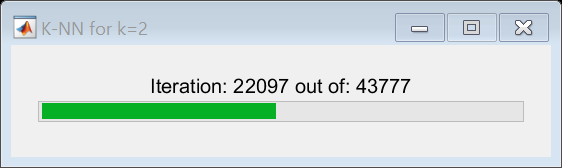

K=2;
yestim = zeros(1,n_data);
%wait bar
f = waitbar(0,'Please wait...', 'Name','K-NN for k=2');
for i=1:n_data
  dato            = x_tr_first(:,i);
  d               = d_euclid(x_tr_first,dato); %time consuming task
  [~,pos]         = sort(d); %time consuming task
  clases_cercanas = y_tr_first(pos(2:K+1));  % La posicion 1 coincide con el dato
  yestim(i)       = moda(clases_cercanas);
  waitbar(i/n_data,f,sprintf('Iteration: %d out of: %d',i,n_data));
end

tasa = length(find(yestim==y))/n_data*100

d). Perform the previous section again for k=10 

K=10;
f = waitbar(0,'Please wait...', 'Name','K-NN for k=10');
for i=1:n_data
  dato            = x_tr_first(:,i);
  d               = d_euclid(x_tr_first,dato);
  [~,pos]         = sort(d); 
  clases_cercanas = y_tr_first(pos(2:K+1));        % La posicion 1 coincide con el dato
  yestim(i)       = moda(clases_cercanas);
  waitbar(i/n_data,f,sprintf('Iteration: %d out of: %d',i,n_data));
end
tasa = length(find(yestim==y))/n_data*100

and k=30.

K=30;
f = waitbar(0,'Please wait...', 'Name','K-NN for k=30');
for i=1:n_data
  dato            = x_tr_first(:,i);
  d               = d_euclid(x_tr_first,dato);
  [~,pos]         = sort(d); 
  clases_cercanas = y_tr_first(pos(2:K+1));        % La posicion 1 coincide con el dato
  yestim(i)       = moda(clases_cercanas);
  waitbar(i/n_data,f,sprintf('Iteration: %d out of: %d',i,n_data));
end
tasa = length(find(yestim==y_tr))/n_data*100

e). Select the value of k from the previously tested ones that has the best hit rate and generate its confusion matrix.

figure;
plotconfusion(categorical(y_tr_first'),categorical(yestim'));

f). Repeat all steps c) to e) for the second half of the total initial characteristics.

K=2;
yestim = zeros(1,n_data);
%wait bar
f = waitbar(0,'Please wait...', 'Name','K-NN for k=2');
for i=1:n_data
  dato            = x_tr_second(:,i);
  d               = d_euclid(x_tr_second,dato); %time consuming task
  [~,pos]         = sort(d); %time consuming task
  clases_cercanas = y_tr_second(pos(2:K+1));  % La posicion 1 coincide con el dato
  yestim(i)       = moda(clases_cercanas);
  waitbar(i/n_data,f,sprintf('Iteration: %d out of: %d',i,n_data));
end
tasa = length(find(yestim==y))/n_data*100

K=10;
f = waitbar(0,'Please wait...', 'Name','K-NN for k=10');
for i=1:n_data
  dato            = x_tr_second(:,i);
  d               = d_euclid(x_tr_second,dato);
  [~,pos]         = sort(d); 
  clases_cercanas = y_tr_second(pos(2:K+1));        % La posicion 1 coincide con el dato
  yestim(i)       = moda(clases_cercanas);
  waitbar(i/n_data,f,sprintf('Iteration: %d out of: %d',i,n_data));
end
tasa = length(find(yestim==y))/n_data*100

K=30;
f = waitbar(0,'Please wait...', 'Name','K-NN for k=30');
for i=1:n_data
  dato            = x_tr_second(:,i);
  d               = d_euclid(x_tr_second,dato);
  [~,pos]         = sort(d); 
  clases_cercanas = y_tr_second(pos(2:K+1));        % La posicion 1 coincide con el dato
  yestim(i)       = moda(clases_cercanas);
  waitbar(i/n_data,f,sprintf('Iteration: %d out of: %d',i,n_data));
end
tasa = length(find(yestim==y_tr))/n_data*100

figure;
plotconfusion(categorical(y_tr_second'),categorical(yestim'));

g). What conclusion can you draw from performing the classifier with the feature halves? Use the confusion matrix for this.

The Dataset is still way to big to calculate all the classifier efficiantly.